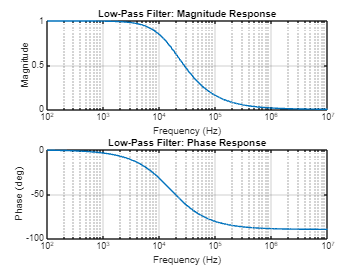

%% Telecommunications Engineering Lab: Analog & Digital Filter Design
% This script analyzes Low-Pass, High-Pass, and Band-Pass transfer functions,
% as well as Butterworth digital noise filtering.

clear; clc; close all;
warning("off");

%% 1. Frequency Vector & Component Definitions
f = 0:1e2:1e7;    % Frequency vector (Hz)
L = 1e-3;         % Inductor (Henry)
C = 1e-7;         % Capacitor (Farad)
R = 100;          % Resistor (Ohm)

Xc = 1 ./ (1i * 2 * pi * f * C);
Xl = 1i * 2 * pi * f * L;

%% 2. Low-Pass Filter (LPF) Response
lp = Xc ./ (R + Xc);
MgL = abs(lp);
PhL = angle(lp) * 180 / pi;

figure('Name', 'Low-Pass Filter');
subplot(2, 1, 1); semilogx(f, MgL); grid on; 
title('Low-Pass Filter: Magnitude Response'); xlabel('Frequency (Hz)'); ylabel('Magnitude');
subplot(2, 1, 2); semilogx(f, PhL); grid on; 
title('Low-Pass Filter: Phase Response'); xlabel('Frequency (Hz)'); ylabel('Phase (deg)');

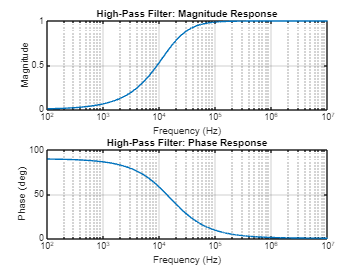


%% 3. High-Pass Filter (HPF) Response
hp = R ./ (R + Xc);
MgH = abs(hp);
PhH = angle(hp) * 180 / pi;

figure('Name', 'High-Pass Filter');
subplot(2, 1, 1); semilogx(f, MgH); grid on; 
title('High-Pass Filter: Magnitude Response'); xlabel('Frequency (Hz)'); ylabel('Magnitude');
subplot(2, 1, 2); semilogx(f, PhH); grid on; 
title('High-Pass Filter: Phase Response'); xlabel('Frequency (Hz)'); ylabel('Phase (deg)');

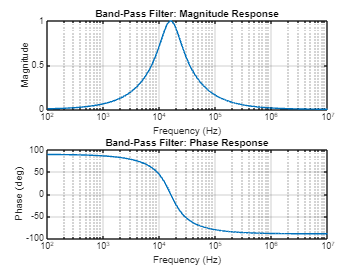


%% 4. Band-Pass Filter (BPF) Response
bp = R ./ (R + Xc + Xl);
MgB = abs(bp);
PhB = angle(bp) * 180 / pi;

figure('Name', 'Band-Pass Filter');
subplot(2, 1, 1); semilogx(f, MgB); grid on; 
title('Band-Pass Filter: Magnitude Response'); xlabel('Frequency (Hz)'); ylabel('Magnitude');
subplot(2, 1, 2); semilogx(f, PhB); grid on; 
title('Band-Pass Filter: Phase Response'); xlabel('Frequency (Hz)'); ylabel('Phase (deg)');

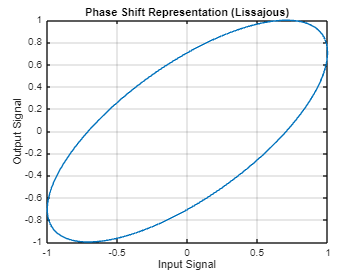


%% 5. Lissajous Phase Comparison
fs = 1e2;
t = 0 : 1/fs : 1;
vin = sin(2 * pi * t);
vout = sin(2 * pi * t + pi/4);

figure('Name', 'Lissajous Curve');
plot(vin, vout); grid on; 
title('Phase Shift Representation (Lissajous)'); xlabel('Input Signal'); ylabel('Output Signal');

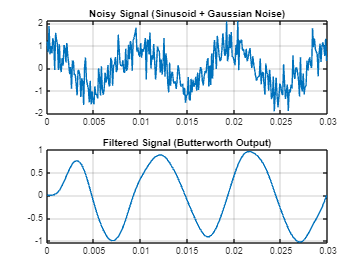


%% 6. Butterworth Filter for Noisy Signal Processing
fs = 1e4;
t = 0 : 1/fs : 1;
f_sig = 100;
x = cos(2 * pi * f_sig * t) + 0.5 * randn(size(t));

% 5th Order Butterworth Low-Pass Filter Design
[b, a] = butter(5, 10 * f_sig / fs / 2);
X_filtered = filter(b, a, x);

figure('Name', 'Butterworth Noise Filtering');
subplot(2, 1, 1); plot(t(1:300), x(1:300)); grid on; title('Noisy Signal (Sinusoid + Gaussian Noise)');
subplot(2, 1, 2); plot(t(1:300), X_filtered(1:300)); grid on; title('Filtered Signal (Butterworth Output)');